# Model 1: free receptor exocytosis

Unliganded EGFR is exocytosed

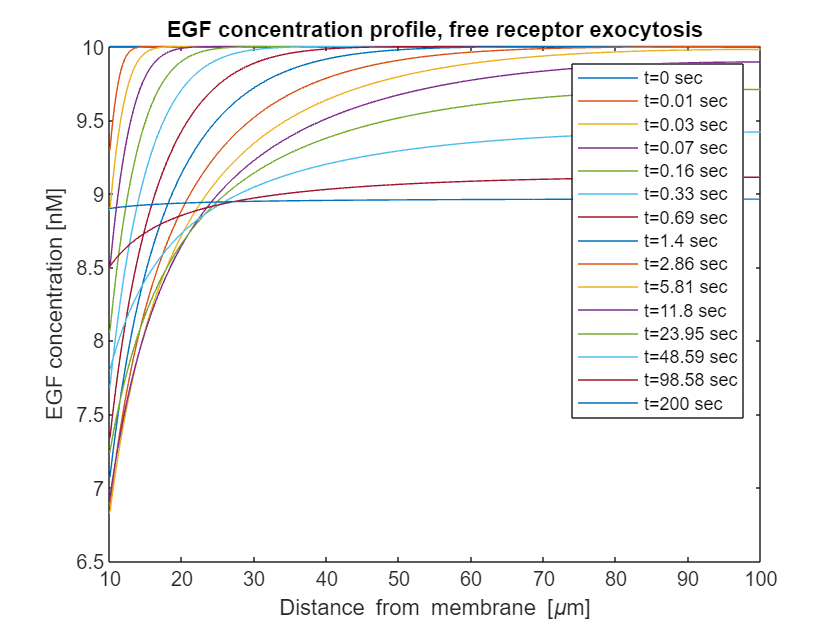

Degf=150; % um2/sec
kon=0.14/60; % 1/(nM * sec)
koff=0.18/60; % 1/sec
cEGF=10; % concentration of EGF (nM) in the bulk solution
thickness=0.05; % thickness of membrane region in which R is present
% PDE function
pdefun=@(x,t,u,dudx) pdefunFun(x,t,u,dudx,Degf,kon,koff);
% generate the time scale
tspan=(0:0.01:200)'; % sec
numOfLines=15;
logMin=log(1);
logMax=log(numel(tspan));
timesToPlot=linspace(logMin,logMax,numOfLines);
timesToPlot=exp(timesToPlot);
timesToPlot=unique(tspan(round(timesToPlot)));
timeIndices=arrayfun(@(x) find(x==tspan,1),timesToPlot);
% end of time scale generation
m=2; % spherical symmetry
a=10; % radius of vesicle/cell in um
xmesh=(a:0.1:100)'; % um
cR=80000; % concentration of receptor at the membrane
pdeicVesicleOut1=@(x) pdeicVesicleOutFun1(x,cEGF,cR,a,thickness);
modelExo1.sol=pdepe(m, pdefun, pdeicVesicleOut1, @pdebc, xmesh, tspan);
modelExo1.freeEgf=plotResults(modelExo1.sol, xmesh, timeIndices, timesToPlot, 'free receptor exocytosis');

# Model 2: diffusion of EGF toward the membrane

A certain amount of EGF, specified by cEGFSource, to the system far from the membrane (simulates adding EGF as in experiment)

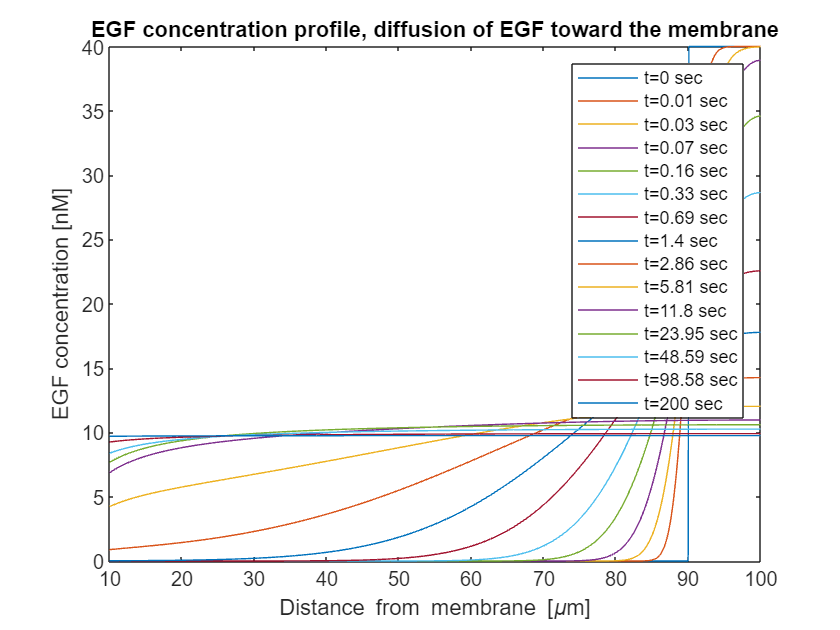

Degf=150; % um2/sec
kon=0.14/60; % 1/(nM * sec)
koff=0.18/60; % 1/sec
m=2; % spherical symmetry
a=10; % radius of vesicle/cell in um
xmesh=(a:0.1:100)'; % um
thickness=0.05; % thickness of membrane region in which R is present
% PDE function
pdefun=@(x,t,u,dudx) pdefunFun(x,t,u,dudx,Degf,kon,koff);
% generate the time scale
tspan=(0:0.01:200)'; % sec
numOfLines=15;
logMin=log(1);
logMax=log(numel(tspan));
timesToPlot=linspace(logMin,logMax,numOfLines);
timesToPlot=exp(timesToPlot);
timesToPlot=unique(tspan(round(timesToPlot)));
timeIndices=arrayfun(@(x) find(x==tspan,1),timesToPlot);
% end of time scale generation
cR=80000; % concentration of receptor at the membrane
sourcePos=90; % EGF is present only at distances larger than sourcePos
cEGFSource=40; % concentration of EGF (nM) at the source
pdeicVesicleOutDiff=@(x) pdeicVesicleOutDiffusionFun(x,cEGFSource,cR,a,thickness,sourcePos);
modelVesicleOutDiff.sol=pdepe(m, pdefun, pdeicVesicleOutDiff, @pdebc, xmesh, tspan);
modelVesicleOutDiff.freeEgf=plotResults(modelVesicleOutDiff.sol, xmesh, timeIndices, timesToPlot, 'diffusion of EGF toward the membrane');

# Model 3: liganded EGFR exocytosis

Initially, EGF is outside the cell in equilibrium with the receptor in the membrane, and ligand-saturated EGFR is added to the membrane

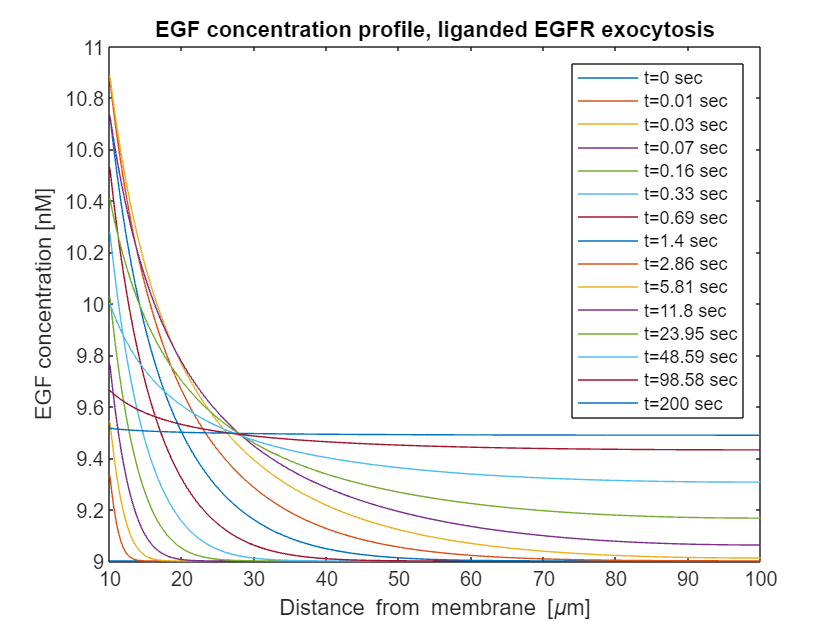

Degf=150; % um2/sec
kon=0.14/60; % 1/(nM * sec)
koff=0.18/60; % 1/sec
kd=koff/kon; % nM
m=2; % spherical symmetry
a=10; % radius of vesicle/cell in um
xmesh=(a:0.1:100)'; % um
thickness=0.05; % thickness of membrane region in which R is present
% PDE function
pdefun=@(x,t,u,dudx) pdefunFun(x,t,u,dudx,Degf,kon,koff);
% generate the time scale
tspan=(0:0.01:200)'; % sec
numOfLines=15;
logMin=log(1);
logMax=log(numel(tspan));
timesToPlot=linspace(logMin,logMax,numOfLines);
timesToPlot=exp(timesToPlot);
timesToPlot=unique(tspan(round(timesToPlot)));
timeIndices=arrayfun(@(x) find(x==tspan,1),timesToPlot);
% end of time scale generation
cR=80000; % concentration of receptor at the membrane
cEGF=9; % concentration of EGF (nM) in the bulk solution
pdeicVesicleOutExocyt=@(x) pdeicVesicleOutExocytFun(x,cEGF,cR,a,thickness,kd);
modelVesicleOutExocyt.sol=pdepe(m, pdefun, pdeicVesicleOutExocyt, @pdebc, xmesh, tspan);
modelVesicleOutExocyt.freeEgf=plotResults(modelVesicleOutExocyt.sol, xmesh, timeIndices, timesToPlot, 'liganded EGFR exocytosis');

# Model 4: continuous EGF exocytosis

A certain amount of EGF, specified by variable 'egfFlux', is continuously exocytosed at the membrane. At the right boundary, the concentration of EGF is kept constant, equal to the initial concentration.

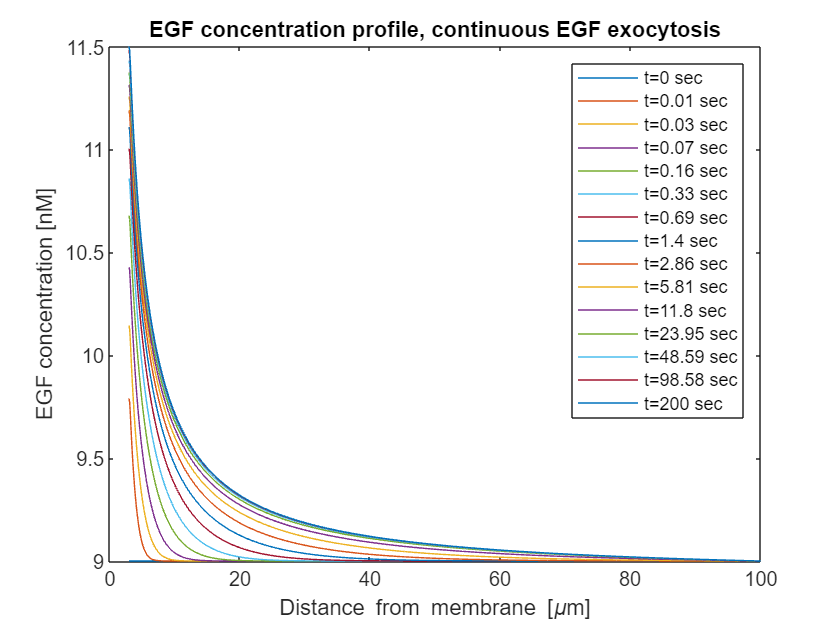

Degf=150; % um2/sec
kon=0.14/60; % 1/(nM * sec)
koff=0.18/60; % 1/sec
kd=koff/kon; % nM
a=3; % radius of vesicle/cell in um
thickness=0.2; % thickness of the membrane in um
egfFlux=625; % this is the amount of EGF added to the system at the membrane, and removed from it at the far side
% PDE function
pdefun4=@(x,t,u,dudx) pdefunFun4(x,t,u,dudx,Degf,kon,koff,a,thickness,egfFlux);
% end of PDE functions
m=2; % spherical symmetry
xmesh=(a:0.1:100)'; % um
% generate the time scale
tspan=(0:0.01:200)'; % sec
numOfLines=15;
logMin=log(1);
logMax=log(numel(tspan));
timesToPlot=linspace(logMin,logMax,numOfLines);
timesToPlot=exp(timesToPlot);
timesToPlot=unique(tspan(round(timesToPlot)));
timeIndices=arrayfun(@(x) find(x==tspan,1),timesToPlot);
% end of time scale generation
cR=80000; % concentration of receptor at the membrane
cEGF=9; % concentration of EGF (nM) in the bulk solution
initialCond=@(x) pdeicEquilibriumFun(x,cEGF,cR,a,thickness,kd);
boundaryCond=@(xl,ul,xr,ur,t) pdebcExo4(xl,ul,xr,ur,t,cEGF);
modelExo4.sol=pdepe(m, pdefun4, initialCond, boundaryCond, xmesh, tspan);
modelExo4.freeEgf=plotResults(modelExo4.sol, xmesh, timeIndices, timesToPlot, 'continuous EGF exocytosis');

# Functions used in the live script

## Models 1-3

function [c,f,s]=pdefunFun(x,t,u,dudx,D,kon,koff)
% u1 - L (EGF)
    % u2 - LR
    % u3 - R
    c=[1 1 1]';
    f=[D*dudx(1) 0 0]';
    s=[koff*u(2)-kon*u(1)*u(3) -koff*u(2)+kon*u(1)*u(3) koff*u(2)-kon*u(1)*u(3)]';
end

function [pl,ql,pr,qr]=pdebc(xl,ul,xr,ur,t)
    pl=[0;0;0];
    ql=[1;1;1]; % no flux at left boundary
    pr=[0;0;0];
    qr=[1;1;1]; % no flux at right boundary
end

## Model 1

function u0=pdeicVesicleOutFun1(x,cEGF,cR,a,thickness)
    % initial conditions for the vesicle model, EGF is outside the vesicle
    if x<=a+thickness
        u0=[cEGF;0;cR];
    else
        u0=[cEGF;0;0];
    end
end

## Model 2

function u0=pdeicVesicleOutDiffusionFun(x,cEGF,cR,a,thickness,sourcePos)
    % initial conditions for the vesicle model, EGF is outside the vesicle,
    % and it diffuses from the far side of the system towards the membrane
    % at the center
    if x<=a+thickness % membrane
        u0=[0;0;cR];
    elseif x>sourcePos % source
        u0=[cEGF;0;0];
    else % everywhere else
        u0=[0;0;0];
    end
end

## Model 3

function u0=pdeicVesicleOutExocytFun(x,cEGF,cR,a,thickness,kd)
    % initial conditions for the vesicle model, EGF is outside the vesicle,
    % in equilibrium with membrane receptors, and then a large amount of
    % ligand-saturated EGFR appears in the membrane
    if x<=a+thickness % membrane
        u0=[cEGF;cEGF*cR/(cEGF+kd) *5 ;kd*cR/(cEGF+kd)]; % [L, LR, R], multiplication of LR by 5 models the exocytosis of EGF-EGFR
    else % everywhere else
        u0=[cEGF;0;0];
    end
end

## Model 4

function [c,f,s]=pdefunFun4(x,t,u,dudx,Degf,kon,koff,a,thickness,egfFlux)
    % u1 - L (EGF)
    % u2 - LR
    % u3 - R
    if x>a+thickness % bulk solution
        % diffusion of EGF, R is not present
        c=[1 1 1]';
        f=[Degf*dudx(1) 0 0]';
        s=[0 0 0]';
    else % membrane
        % source of EGFR-EGF
        % binding equilibrium of EGF
        c=[1 1 1]';
        f=[Degf*dudx(1) 0 0]';
        s=[koff*u(2)-kon*u(1)*u(3)+egfFlux -koff*u(2)+kon*u(1)*u(3) koff*u(2)-kon*u(1)*u(3)]';
    end
end

function u0=pdeicEquilibriumFun(x,cEGF,cR,a,thickness,kd)
    % initial conditions for the vesicle model, EGF is outside the vesicle,
    % in equilibrium with membrane receptors
    if x>a+thickness % bulk solution
        u0=[cEGF;0;0];
    else % membrane
        u0=[cEGF; cEGF*cR/(cEGF+kd); kd*cR/(cEGF+kd)]; % [L, LR, R]
    end
end

function [pl,ql,pr,qr]=pdebcExo4(xl,ul,xr,ur,t,cEGF)
    pl=[0;0;0];
    ql=[1;1;1]; % no flux at left boundary
    pr=[ur(1)-cEGF;0;0]; % EGF cc at the right boundary is kept constant
    qr=[0;1;1];
end

## All models

function freeEgf=plotResults(solution,xmesh,timeIndices,timesToPlot,titleText)
    % u1 - L (EGF)
    % u2 - LR
    % u3 - R
    figure;
    egfMatrix=solution(:,:,1);
    freeEgf=zeros(numel(xmesh),numel(timeIndices));
    i=1;
    while i<=numel(timeIndices)
        freeEgf(:,i)=egfMatrix(timeIndices(i),:)';
        plot(xmesh,freeEgf(:,i));
        if i==1
            hold on;
        end
        i=i+1;
    end
    title(['EGF concentration profile, ',titleText]);
    xlabel('Distance from membrane [\mum]');
    ylabel('EGF concentration [nM]')
    legendText=arrayfun(@(x) num2str(x),timesToPlot,'UniformOutput',false);
    legendText=cellfun(@(x) ['t=',x,' sec'],legendText,'UniformOutput',false);
    legend(legendText);
end
